# Algoritmos de cinemática inversa

Dificultad: Alta (Teoría, Básico)

clear all
close all

## Estación de trabajo

- Se parte de una estación robótica clásica con un robot variable y una serie de objetos de trabajo

- El robot de la estación está definido como un subsistema por lo que se puede variar

% Abrir estación
Estacion= 'C15S1_Robot_Variable';
% Abrir robot
NomRobot= 'ABB_irb120';
%NomRobot= 'ABB_Gofa'; 

r1= load(NomRobot)

r1 = struct with fields:
        Carga: [1×1 Pieza]
        Pinza: [1×1 Pieza]
     TcpCarga: 'Body10'
     TcpPinza: 'Body09'
    baseRobot: [0 0 0 0 0 0]
           q0: [0 0 0 0 0 0]
        robot: [1×1 rigidBodyTree]



deg= pi/180;

% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Cin como variables del sistema 
% No deben modificarse en el programa 
q0_= zeros(1,6);
pose_= randn(3,3)*1e-3;

% Los elementos relativos al robot están definidos en la variable r1
% Se debe poner esos elementos en Simulink

% Esfera
Esf= Pieza('Esfera');
Esf.Base([[0,-350,0]*1e-3, [0,0,0]*deg]);
Esf.Color([0,0.3,0.8,0.7]);

% Mesa inclinada (icono constante)
MesInc= Pieza('MesaInclinada');
MesInc.Base([[0,0, 0]*1e-3, [0,0,0]*deg]);
x1= [0.4000, 0.1330, 0];
x2= [0.1500, -0.3000, 0];
y1= [0.7232, -0.0536, 0.1000];
MesInc.Tcp(Prod(x1,x2,y1));

MesInc.Color([0.3, 0.8, 0.2, 0.7]);

% Cilindro (icono constante)
Cil= Pieza('Cilindro');
Cil.Base([[0, 300, 900]*1e-3, [0, 90, 0]*deg]);
Cil.Color([0.4,0.7,0.2,0.7]);

% Tablero (icono constante)
Tab= Pieza('Tablero');
Tab.Base([[200, 200, 100]*1e-3, [0, 0, 30]*deg]);
Tab.Color([0.2,0.5,0.1,0.7])


% Es preciso abrir la estación para modificar el subsystem
open_system(Estacion)

% Ver el robot que hay
%get_param([Estacion,'/Robot1'], 'ReferencedSubsystem')
% Modificar dicho robot
% Es preciso abrir primero la estación (parece)
set_param([Estacion,'/Robot1'], 'ReferencedSubsystem', NomRobot)
get_param([Estacion,'/Robot1'], 'ReferencedSubsystem')

ans = 'ABB_irb120'


rob= Cin(r1.robot, Estacion, r1.TcpCarga, r1.q0);

Herramienta: Body10
Simulación. Ts= 0.100 m/s


### Diagrama Simulink Multi-Body

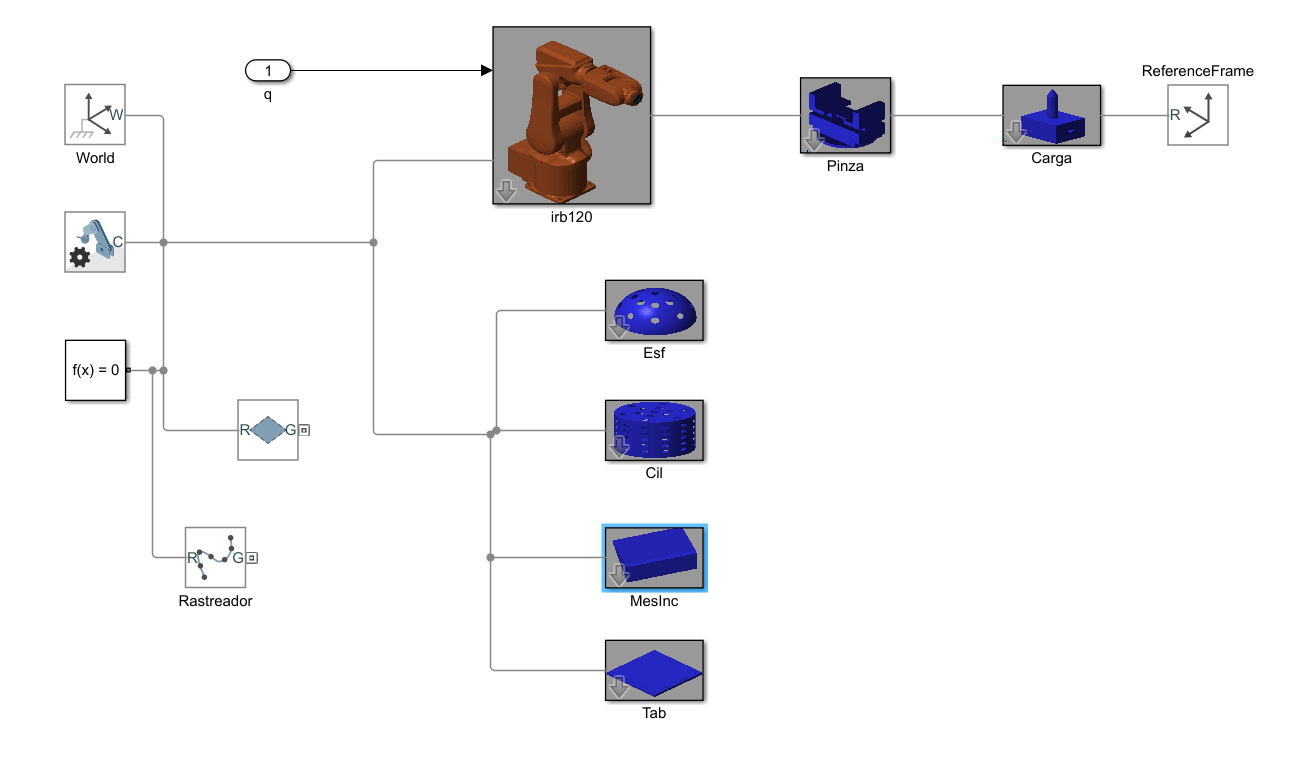

## Algoritmo de pesos

- Se usa el algoritmo $InverseKinematics$de la librería *Robotic Toolbox*

- Es el algoritmo básico que obtiene la cinemática inversa con optimización local con $6$ objetivos, llegar al $[x,y,z,R_z,R_y,R_x]$ deseado minimizando el error.

- En realidad, internamente Robotic Toolbox usa $[R_z,R_y,R_x,x,y,z,]$

- Por ejemplo $w= [1,1,1,0,0,0]$ la cinemática inversa se halla con solo la posición

% Punto respecto de mesa inclinada
punto= [[50,50,0]*1e-3,[0,0,180]*deg];
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
rob.Rec
% Todos los pesos iguales a 1
rob.W();
rob.MoveJ(punto, MesInc);
% Solo se valora la posición
rob.W([1,1,1,0,0,0]);
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
rob.MoveJ(punto, MesInc);

rob.Rep

ans =   Simulink.SimulationOutput:

                   tout: [32x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Algoritmo de pesos generalizado

- Uso del objeto de Robotic Toolbox $generalizedInverseKinematics$

#### Posibles objetivos

- $constraintCartesianBounds$: Se define los límites cartesianos en los que se puede mover el robot.

- $constraintPositionTarget$: Se define la posición $[x,y,z]$ a la que se desea llegar.

- $constraintOrientationTarget$: Se define la orientación en cuaternios. 

- $constraintPoseTarget$: Se define la matriz homogénea y el peso de posición y orientación.

- $constraintJointBounds$: Se define los límites de las articulaciones, por defecto, las que tiene el robot.

- $constraintRevoluteJoint$: Se define los límites de las articulaciones entre dos elementos.

- $constraintPrismaticJoint$: Fija una matriz homogénea entre dos elementos.

- $constraintDistanceBounds$: Fija la distancia entre dos articulaciones *bodies* del componente *RigidBody.*

- $constraintAiming$: Orientación del tcp, en ejes $[x,y,z]$ 

#### Uso con $Cin()$

- Se introducen los objetivos que se desean, por defecto, $constraintPoseTarget$

- Las restricciones más usadas son la del espacio cartesiano $constraintCartesianBounds$ y redefinir los límites de los ejes del robot $constraintJointBounds$

- Se usa el algoritmo generalizado

- Si los objetivos son incompatibles, el algoritmo tarda mucho

#### Por defecto


punto= [[100,100,0]*1e-3,[0,0,180]*deg];
% Generalizado por defecto
rob.GIKGen();
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
rob.Rec;
rob.MoveJ(punto, MesInc);

#### Con restricción en ejes cartesianos

- Se ha puesto objetivos incompatibles para ver el efecto


% Define los límites cartesianos en los que se mueve el robot
% Se desea mover la carga
cartesian = constraintCartesianBounds(r1.TcpCarga);
cartesian.Bounds = [-inf, inf ; ...
                    -inf, inf; ...
                     100*1e-3, inf];
% Peso de la restricción
cartesian.Weights= [0,0,10];
rob.GIKGen('cartesian', cartesian);
% Movimiento
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
rob.MoveJ(punto, MesInc);


#### Restricciones en ejes cartesianos y límites de ejes

- Son objetivos incompatibles por lo que no llega al punto


% Se ponen restricciones a los ejes del robot
joint= constraintJointBounds(r1.robot);
% Se fija el eje 1 a cero
joint.Bounds(2,:)= [0,0]*deg;
joint.Weights= 10*ones(1,6);
rob.GIKGen('cartesian', cartesian, 'jointbounds', joint);
% Movimiento
rob.MoveAbsJ([0,0,0,0,90,0]*deg);
rob.MoveJ(punto, MesInc);


ans =   Simulink.SimulationOutput:

                   tout: [54x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Algoritmo algebraico de cinemática inversa

- Solo es válido para robot con los $3$ últimos ejes esféricos

- Es cuando un robot tiene el $4$, $5$ y $6$ en $ZYZ$ con los ejes que coinciden en un punto.

- El *ABB irb120* es un caso, pero los robots colaborativos no.

#### Generar el fichero algebraico del robot en $Cin()$

- Se debe especificar los *bodies* que se quieren de TCP

- Se genera un fichero por *body*

- Los ficheros se generan en el directorio actual, por lo que es interesante poner el sistema en el directorio donde se desean guardar

- Es mucho más rápido que los demás

- El robot ABB Gofa no tiene muñeca esférica

rob.AIKGen('ABB_Gofa', {r1.TcpPinza, r1.TcpCarga})

- Se prueba con el ABB irb120

- Se cambia en la estación de robot para luego moverlo

NomRobot= 'ABB_irb120';

r1 = struct with fields:
        Carga: [1×1 Pieza]
        Pinza: [1×1 Pieza]
     TcpCarga: 'Body10'
     TcpPinza: 'Body09'
    baseRobot: [0 0 0 0 0 0]
           q0: [0 0 0 0 0 0]
        robot: [1×1 rigidBodyTree]


r1= load(NomRobot)
set_param([Estacion,'/Robot1'], 'ReferencedSubsystem', NomRobot)

ans = 'ABB_irb120'

get_param([Estacion,'/Robot1'], 'ReferencedSubsystem')


Herramienta: Body10
Simulación. Ts= 0.100 m/s


rob = Herramienta: Body10
Modelo: C15S1_Robot_Variable
Ts= 0.100 m/s
Entradas= 1-6
IK alg= W IK (pesos)

rob= Cin(r1.robot, Estacion, r1.TcpCarga, r1.q0)

rob.AIKGen(NomRobot, {r1.TcpPinza, r1.TcpCarga})

- Se mueve el robot con el algoritmo algebraico

% Si ya está creado el fichero
rob.AIKGen(NomRobot)

punto= [[100,100,0]*1e-3,[0,0,180]*deg];

% Generalizado por defecto

rob.MoveAbsJ([0,0,0,0,90,0]*deg);
rob.MoveJ(punto, MesInc);

## Algoritmo incremental del Jacobiano 

- Se mueve a incrementos usando el concepto de Jacobiano $\Delta q= J^{-1}*\Delta pose$, donde $q$ son la posición-grados ejes y $pose=[x,y,z,R_z,R_y,R_x]$ la posición cartesiana del TCP

- Hay que tener cuidado con los incrementos de los ángulos usando la fórmula de Rodrigues. El incremento entre $180$ y $-180$ es $0$, no $360$

- Se da un límite a la norma del incremento para evitar inestabilidades, si no se cumple, no se tiene en cuenta el incremento angular (defecto 1)

- Va más rápido que un algoritmo normal, no tiene que resolver el algoritmo de optimización iterativo con un número de pasos elevado, usa los mismos pasos que puntos

- Puede ser menos preciso ya que calcula el incremento en cada paso, se puede incrementar el número de pasos para ganar precisión

rob.JacIK(1);

JacIK activado


punto= [[100,100,0]*1e-3,[0,0,180]*deg];

rob.MoveAbsJ([0,0,0,0,90,0]*deg);
rob.MoveJ(punto, MesInc);

% Incrementamos el número de puntos para ganar precisión
rob.Npts(30);
rob.Ts(0.1);

rob.MoveAbsJ([0,0,0,0,90,0]*deg);
rob.MoveJ(punto, Tab);